## 0. 相关参数

clear;clc;close all
%% 作业线相关参数
% 垛位数量P=40
P=40;
% 取料作业线数量U-3
U=3;
% 取料机总数R=5
R=5;
% 横向作业线数量V=2
V=2;
% 装船作业线W=3
W=3;
% 泊位数 K=3
K=3;
% 煤料种类C=12
C=12;

%% 船舶任务相关
% 船舶总数S=30
S=30;
% 任务总数M=185
M=185;
% 优化期时长T=310h
T=310;

%% 各部分编号集合
Para.Pset=1:P;
Para.Uset=1:U;
Para.Rset=1:R;
Para.Vset=1:V;
Para.Wset=1:W;
Para.Kset=1:K;

%% 读取表格数据
shipmission = readtable('V08170938调度数据.xlsx', 'Sheet', '到港信息提取 - Matlab');


%% 各船舶s进港时间Para.t_arr{s}
for i=1:S
    Para.t_arr{i}=shipmission.Date(i);
end

%% 各船舶s泊位k占用情况Para.betaSK{s,k}
Para.betaSK = zeros(S,K);
for i = 1:numel(Para.betaSK)
    Para.betaSK(i) = 0;
end

for i=1:S
     Para.betaSK(i,shipmission.Berth(i))=1;
end

%% 各船舶任务集合Para.SMset{s,m}
for i=1:S
    Para.SMset{i}=shipmission.Mission_start(i):shipmission.Mission_end(i);
end

%% 各船舶s任务m占用情况Para.thetaSM{s,m}
Para.thetaSM = zeros(S,M);
for i = 1:numel(Para.thetaSM)
    Para.thetaSM(i) = 0;
end

for i=1:S
    for j=shipmission.Mission_start(i):shipmission.Mission_end(i)
     Para.thetaSM(i,j)=1;
    end
end

%% 取料作业线u可达性垛位p集合Para.alphaUPset{u}
Para.alphaUPset{1}={5,10,15,20,25,30,35,40};
Para.alphaUPset{2}={3,8,13,18,23,28,33,38,4,9,14,19,24,29,34,39
};
Para.alphaUPset{3}={1,6,11,16,21,26,31,36,2,7,12,17,22,27,32,37
};

%% 取料作业线u与垛位p可达性Para.alphaUP{u,p}
Para.alphaUP = zeros(U,P);
for i = 1:numel(Para.alphaUP)
    Para.alphaUP(i) = 0;
end


for i=1:U
    for j =1:length(Para.alphaUPset{i})
        Para.alphaUP(i,Para.alphaUPset{i}{j})=1;
    end
end
%% 取料作业线u可达性取料机r集合Para.lambdaURset{u}
Para.lambdaURset{1}={1};
Para.lambdaURset{2}={2,3};
Para.lambdaURset{3}={4,5};

%% 取料作业线u与取料机r可达性Para.lambdaUR{u,r}
Para.lambdaUR = zeros(U,R);
for i = 1:numel(Para.lambdaUR)
    Para.lambdaUR(i) = 0;
end

for i=1:U
    for j =1:length(Para.lambdaURset{i})
        Para.lambdaUR(i,Para.lambdaURset{i}{j})=1;
    end
end

%% 装船作业线w可达性泊位k集合Para.alphaWKset{w}
Para.alphaWKset{1}={1,2};
Para.alphaWKset{2}={1,2,3};
Para.alphaWKset{3}={2,3};

%% 装船取料作业线w与泊位k可达性Para.alphaWK{w,k}
Para.alphaWK = zeros(W,K);
for i = 1:numel(Para.alphaWK)
    Para.alphaWK(i) = 0;
end

for i=1:W
    for j =1:length(Para.alphaWKset{i})
        Para.alphaWK(i,Para.alphaWKset{i}{j})=1;
    end
end

%% 两台取料机位于同一轨道上Para.Krr{r,r}
Atem=[1	0	0	0	0
0	1	1	0	0
0	1	1	0	0
0	0	0	1	1
0	0	0	1	1];

Para.Krr=Atem;

%% 取料机取料速度t/h，Para.Vr(r)
Para.Vr={6000,6000,3000,6000,3000};

%% 堆垛p至泊位k运输时长，单位h，Para.DtPK(p,k)
load dataDt
tt=[tt1',tt2',tt2'];
Para.DtPK=tt;

%% 装船任务m干散货需求种类Para.Cm{m}
%% 装船任务m干散货需求量Para.Dm{m}
% 从数据dataMCD获取随机分配的任务需求种类MC
load dataMCD
Para.Cm=MC;
Para.Dm=MD;

%% 堆垛任务m可选垛位编号集合Para.Pm{m}
% 堆垛类型矩阵pn
pn=[2	1	12	7	10	10	6	3
8	3	2	4	5	9	8	11
1	5	4	8	6	9	11	10
4	5	7	3	8	1	2	6
7	7	2	4	1	12	3	5
];
pnn=reshape(pn,1,40);

for i=1:M
    Para.Pm{i}=find(pnn==Para.Cm(i));
end

%% 装船任务m与垛位p可达性Para.gammaMP{m,p}
% 由堆垛任务m可选垛位编号集合Para.Pm{m}推算

Para.gammaMP=zeros(M,P);
for m=1:M
    for j=1:length(Para.Pm{m})
        p=Para.Pm{m}(j);
        Para.gammaMP(m,p)=1;
    end
end

%% 同一泊位k两船舶s靠泊优先级Para.Zss{s,s}
Para.Zss=zeros(S,S);
for k=1:K
    for s=1:S-1
        for s1=s+1:S
            if Para.betaSK(s,k)*Para.betaSK(s1,k)==1
                if Para.t_arr{s}<Para.t_arr{s1}
                    Para.Zss(s,s1)=1;
                else
                    Para.Zss(s1,s)=1;
                end
            end
        end
    end
end

%% 装船任务m与泊位k之间的可达性Para.deltaMK{m,k}
Para.deltaMK=zeros(M,K);
for s=1:S
    %从船舶s对应任务集合Para.SMset{s}中获取m
    for m=Para.SMset{s}(1):Para.SMset{s}(end)
        %从船舶s对应泊位k
        k=shipmission.Berth(s);
        Para.deltaMK(m,k)=1;
    end
end

%% 装船机从泊位k移动到k'时长Para.paiKK{k,k}
Para.paiKK=zeros(K,K);
Para.paiKK(1,2)=3/60;
Para.paiKK(2,1)=3/60;
Para.paiKK(1,3)=6/60;
Para.paiKK(3,1)=6/60;
Para.paiKK(2,3)=2.5/60;
Para.paiKK(3,2)=2.5/60;

%% 船舶m各项作业时长，单位h
% 回旋时长[10,20]min，Para.t_tr{s} 
% 解缆时长[15,30]min，Para.t_un{s} 
% 辅助作业时长[30,60]min，Para.t_aux{s} 
% ttr=round(rand(1,S)*(10))+10;
% tun=round(rand(1,S)*(15))+15;
% taux=round(rand(1,S)*(30))+30;
load dataT
for s=1:S
    Para.t_tr=ttr/60;
    Para.t_un=tun/60;
    Para.t_aux=taux/60;
end

% 两项装船任务占用同一泊位两侧的两台装船机的作业间隔10min,Para.eta
Para.eta=10/60;

%% 各船舶进港日期转换为进港时刻
for s=1:30
    Para.t_ar{s}=Para.t_arr{s}-Para.t_arr{1};
end

### 1. uvw之间可达性

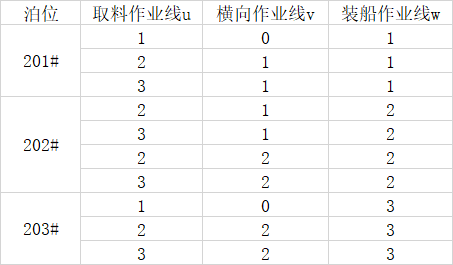


%% 横向作业线u与取料作业线v和装船作业线w可达性Para.alphaUVW{u,v,w}
% 注意：两条横向作业线V=2，{1,0,1}/{1,0,3}=1表示取料线1可以直接和装船线1/3相连；
% 因此v有0,1,2三个取值；元胞中的v=1为实际略过横线，v=2为横线1，v=3为横线2
Atem=zeros(3,3,3);
Btem=[1,2,3,2,3,2,3,1,2,3;1,2,2,2,2,3,3,1,3,3;1,1,1,2,2,2,2,3,3,3];
[~,n]=size(Btem);
for i=1:n
    Atem(Btem(1,i),Btem(2,i),Btem(3,i))=1;
end

Para.alphaUVW=Atem;

save dataPara Para P R U V W K C S M T

## 1. 取料作业线与垛位、取料作业线与取料机

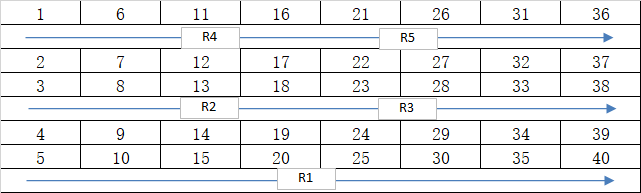

## 2. （非必要不执行：随机生成数据）随机生成装船任务m干散货需求种类c矩阵MC与需求量DM

%% 装船任务m干散货需种类MC与需求量MD
% 随机分配需种类
C = 12; M=185;S=30;
for i=1:S
    %随机生成3类干散货编号
    cc=round(rand(1,3)*(C-1))+1;
    %每一船舶s所有装船任务最多装载3类干散货
    for j=Para.SMset{i}(1):Para.SMset{i}(end)
        dd=round(rand(1)*(3-1))+1;
        MC(j)=cc(dd);
    end
    %对于每个船舶s随机生成一个80-120之间的装载量±2范围内5个值的装载向量；
    ss=100*(round(rand(1)*(40-1))+80+(-2:1:2));
    %对于每个船舶s随机选择3个可选装载量
    sss=round(rand(1,3)*(5-1))+1;
    for j=Para.SMset{i}(1):Para.SMset{i}(end)
        %各任务随机从3个可选装载量进行分配
        ssss=sss(round(rand(1)*(3-1))+1);
        MD(j)=ss(ssss);
    end
end

save dataMCD MC MD

## 3.（非必要不执行：随机生成数据）随机生成各附加时长常值

% 回旋时长[10,20]min，Para.t_tr{s} 
% 解缆时长[15,30]min，Para.t_un{s} 
% 辅助作业时长[30,60]min，Para.t_aux{s} 
ttr=round(rand(1,S)*(10))+10;
tun=round(rand(1,S)*(15))+15;
taux=round(rand(1,S)*(30))+30;

save dataT ttr tun taux

## 4. 进港日期转换为时间

S=30;load dataPara.mat

for i=1:30
    Para.t_ar{i}=Para.t_arr{i}-Para.t_arr{1};
end
    